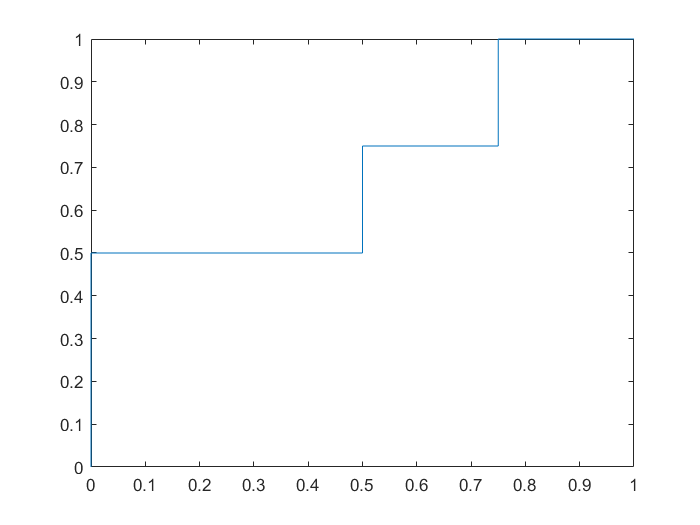

[tpr, fpr, xcorr] = roc([1,  0,  1,  0,   1,  0,  1, 0],[ 0.967, 0.448, 0.568, 0.879, 0.015, 0.780, 0.978, 0.004]);
plot(fpr,tpr);

factors = glmfit(predictor,response,'binomial');
prob = glmval(factors,predictor,'logit');

[x,y,thre,AUC] = perfcurve(response,prob,1);

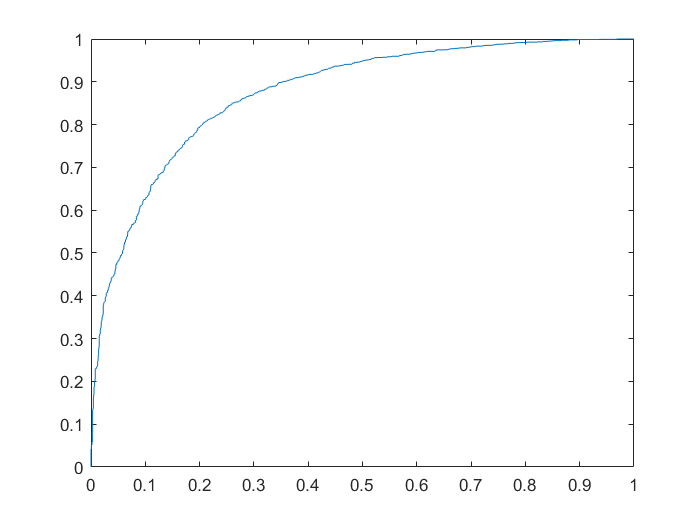

figure(1);
plot(x,y);

[AUC];

train_Predictor = predictor(1:3000,:);
train_Response = response(1:3000);


factors_train = glmfit(train_Predictor,train_Response,'binomial');

prob_train = glmval(factors_train,train_Predictor,'logit');

[x_train,y_train,thre_train,AUC_train] = perfcurve(train_Response, prob_train,1);

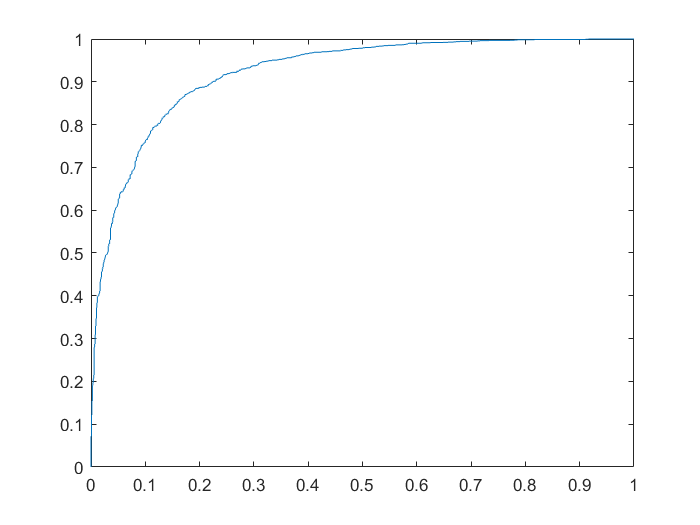

plot(x_train,y_train);

[AUC_train]

AUC_train = 0.9219

validation_predictor = predictor(3000:4000,:);
validation_response = response(3000:4000,:);


prob_validation = glmval(factors_train,validation_predictor,'logit');

[x_validation,y_validation,thre_validation,AUC_validation] = perfcurve(validation_response,prob_validation,1)

x_validation =          0
    0.2596
    0.2641
    0.2664
    0.2686
    0.2709
    0.2731
    0.2754
    0.2777
    0.2799


y_validation =          0
    0.1541
    0.1595
    0.1649
    0.1685
    0.1685
    0.1720
    0.1756
    0.1756
    0.1774


thre_validation =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


AUC_validation = 0.4645

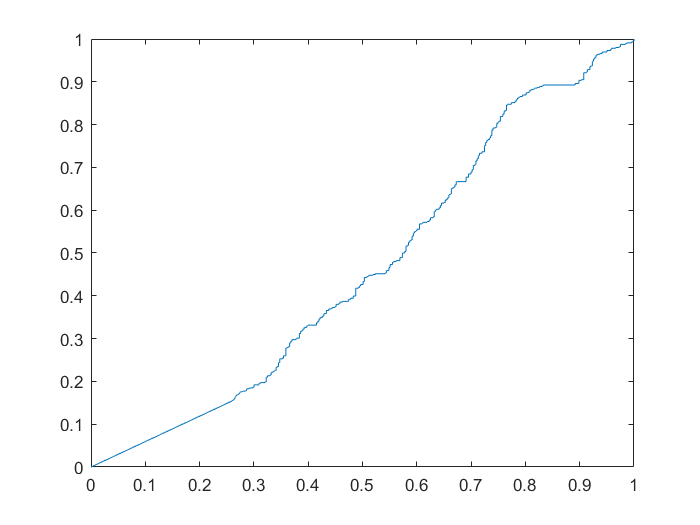

plot(x_validation,y_validation)

difference = AUC_train-AUC_validation

difference = 0.4573